# AFC Ensmeble Training

clear;
close all;
bdclose('all');
addpath('/home/momentumlab/Documents/git/AI-CPS-Ensemble/AFC/model')
addpath('/home/momentumlab/Documents/git/AI-CPS-Ensemble/AFC/DRL_training/trained_agent')
addpath('/home/momentumlab/Documents/git/AI-CPS-Ensemble/AFC/abstraction/')

## Environment Setup

Ts = 0.1;               % sample time for execution
T = 30;                 % simulation duration in sec
Ts_sample = Ts;         % sample time for data extraction
fuel_inj_tol=1.0;
MAF_sensor_tol=1.0;     % MAF sensor error factor
AF_sensor_tol=1.0; 
pump_tol=1.0;
kappa_tol=1.0;
tau_ww_tol=1.0;
fault_time=50;
kp=0.04;
ki=0.14;

fuel_inj_max = 1.66;    % max/min controller output (fuel injection)
fuel_inj_min = 0.13;

%The engine speed is constrained to the range [900,1100].
min_Engine_Speed = 900;
max_Engine_Speed = 1100;

%The pedal angle is constrained to the range [8.8,61.1].
min_Pedal_Angle = 1;
max_Pedal_Angle = 52;

change_freq_PA = 4;         % input signal change value every 3 sec
change_freq_ES = 2;

power_threshold = 70;       % pedal angle threshold for power mode
max_mu_normal = 0.02;       % max mu for normal mode
max_mu_power = 0.2;         % max mu for power mode
steady_mu_max = 0.02;       % max mu for steady state in normal mode
edge_mu_max = 0.05;         % max mu for rising/falling edge in normal mode
AF_ref_normal = 14.7;       % ref A/F for normal mode
AF_ref_power = 12.5;        % ref A/F for power mode
mu_tol_normal = 0.5;        % mu value to terminate the episode
time_tol = 10;              % time tolerence, to avoid the initial large mu value
seed_PA = 0;
seed_ES = 0;    

sim_num = 1000;     % numbers of simulations
rewardDim = 2;      % reward dimension [lateral deviation, relative yaw angle]
isEval = false;     % random input generation

## Load Constitutional Controllers

myFolder = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/AFC/DRL_training/trained_agent";
% check if folder path is valid
if ~isfolder(myFolder)
    errorMessage = sprintf('Error: The following folder does not exist:\n%s', myFolder);
    uiwait(warndlg(errorMessage));
    return;
end

% load all .MAT files under determined folder
filePattern = fullfile(myFolder, '*.mat');
matFiles = dir(filePattern);
[fileNumber, ~]= size(matFiles);

% get selected DRL agents
matFiles = struct2cell(matFiles);
allAgentName = matFiles(1,:);
allAgentName = convertCharsToStrings(allAgentName)';
allAgentName = [allAgentName(1:3);allAgentName(5:10)];

% load trained RL controllers
rlAgentName = allAgentName;

agent1 = load(rlAgentName(1)).agent;
agent2 = load(rlAgentName(2)).agent;
agent3 = load(rlAgentName(3)).agent;
agent4 = load(rlAgentName(4)).agent;
agent5 = load(rlAgentName(5)).agent;
agent6 = load(rlAgentName(6)).agent;
agent7 = load(rlAgentName(7)).agent;
agent8 = load(rlAgentName(8)).agent;
agent9 = load(rlAgentName(9)).agent;

numRL = 9;      % num of RL controllers
rewardWeights = [0.5, 0.5, 0.05];  % rewardWeights for candidate agents
isTerminate = false;               % candidate agents do not terminate
predIndexVector = 3;               % only take the total reward as the prediction result

% load abstracted MDP
abstractMDP = load("AFC_abstract_model").abModel;
actionUB = abstractMDP.actionUB;
rewardUB1 = abstractMDP.rewardUB_1;
rewardUB2 = abstractMDP.rewardUB_2;
rewardToIndex = abstractMDP.rewardToIndexTable;
tranTable = abstractMDP.tranTable;
stateTable = tranTable(:,1);
actionTable = tranTable(:,2);

## DRL Obs/Act configuration

Creating an environment model includes action, obervation

**Observation**: 

- Air-by-Fuel ratio

- Engine speed

- Throttle angle

- Throttle flow

- +9 Predictions

**Action**: Fuel injected, [0.13, 1.66]

% if use prediction as additional features
isPred = false;

if isPred
% observation
    obsInfo = rlNumericSpec([14 1],...
        'LowerLimit', -inf*ones(14,1),...
        'UpperLimit', inf*ones(14,1));
    obIsnfo.Name = 'observations';
    obsInfo.Description = 'state, predicted semantics';
    numObservations = obsInfo.Dimension(1);
else
    obsInfo = rlNumericSpec([5 1],...
        'LowerLimit', -inf*ones(5,1),...
        'UpperLimit', inf*ones(5,1));
    obIsnfo.Name = 'observations';
    obsInfo.Description = 'state';
    numObservations = obsInfo.Dimension(1);
end

% action
actInfo = rlFiniteSetSpec([1 2 3 4 5 6 7 8 9]);
actInfo.Name = 'controller selection';
numActions = actInfo.Dimension(1);

mdl = 'AFC_ensemble_RL_training';
agentblk = [mdl, '/Air Fuel Control Model/Ensemble Control System/ensemble_RL'];

% Build the environment interface object.
env = rlSimulinkEnv(mdl,agentblk,obsInfo,actInfo);

% Fix the random generator seed for reproducibility
% rng(0);

## DRL Agent Configuration

Create a network to be used as underlying critic approximator

criticNetwork = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(64,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(128,'Name','CriticStateFC2')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(256,'Name','CriticCommonFC1')
    reluLayer('Name','CriticCommonRelu2')
    fullyConnectedLayer(128,'Name','CriticCommonFC2')
    reluLayer('Name','CriticCommonRelu3')
    fullyConnectedLayer(64,'Name','CriticCommonFC3')
    reluLayer('Name','CriticCommonRelu4')
    fullyConnectedLayer(1,'Name','CriticOutput')];

% convert the network to a dlnetwork object
criticNetwork = dlnetwork(criticNetwork);

% create critic based on the network approximator
critic = rlValueFunction(criticNetwork,obsInfo,'UseDevice','cpu');

% create a network to be used as underlying actor approximator
actorNetwork = [
    featureInputLayer(prod(obsInfo.Dimension),'Normalization','none','Name','observation')
    fullyConnectedLayer(64,'Name','ActorFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(128,'Name','ActorFC2')
    reluLayer('Name','ActorRelu2')
    fullyConnectedLayer(128,'Name','ActorFC3')
    reluLayer('Name','ActorRelu3')
    fullyConnectedLayer(64,'Name','ActorFC4')
    reluLayer('Name','ActorRelu4')
    fullyConnectedLayer(length(actInfo.Elements),'Name','ActorFC5')                       
    softmaxLayer('Name','actionProb')];

actor  = rlDiscreteCategoricalActor(actorNetwork,obsInfo,actInfo);

**Noise model:**

- It is common to set `StandardDeviation*sqrt(Ts)` to a value between 1% and 10% of your action rang.

- To increase exploration, you can reduce the `StandardDeviationDecayRate`.

% Optimization options for actors and critics
myCriticOpts=rlOptimizerOptions(...
    'LearnRate',2e-4,...
    'GradientThreshold',1,...
    'GradientThresholdMethod',"l2norm",...
    'L2RegularizationFactor', 1e-4,...
    'Optimizer',"adam");

myActorOpts=rlOptimizerOptions(...
    'LearnRate',1e-4,...
    'GradientThreshold',1,...
    'GradientThresholdMethod',"l2norm",...
    'L2RegularizationFactor', 1e-4,...
    'Optimizer',"adam");

agentOptions = rlACAgentOptions(...
    'CriticOptimizerOptions', myCriticOpts,...
    'ActorOptimizerOptions',myActorOpts,...
    'SampleTime',Ts,...
    'NumStepsToLookAhead',10,...
    'EntropyLossWeight',0.01,...
    'DiscountFactor',0.99);

% agent creation
agentEnsemble = rlACAgent(actor, critic, agentOptions);

## **Training Configurations**

Change the weights distribution among subsitutional rewards

maxepisodes = 2000; 
maxsteps = ceil(T/Ts);
window_length = 20;

% change reward weights distribution
ensembleRewardWeights = [0.7, 0.3, 0.05];

trainOpts = rlTrainingOptions(...
    'MaxEpisodes', maxepisodes, ...
    'MaxStepsPerEpisode', maxsteps, ...
    'ScoreAveragingWindowLength',window_length, ...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue', 1.1*sum(ensembleRewardWeights)*maxsteps*0.95,...
    'Verbose', false,...
    'Plots','training-progress',...
    'UseParallel',false);

doTraining = true;

if doTraining
    % Train the agent.
    isEnsembleTerminate = true;
    trainingStats = train(agentEnsemble,env,trainOpts);
else
%     agent = load('preTrainedAgent.mat');
%     agent = agent.agent;
end

## Save trained agent 

Save DRL agent with training configurations, agent configurations and training progress info

isSave = false;

if isSave
    dateOfTrain = date;
    if isPred
        agentName = ['AFC-ensemble-pred--AC-9-RL-0-PID-', dateOfTrain(1:end-5)];
    else
        agentName = ['AFC-ensemble-no-pred--AC-9-RL-0-PID-', dateOfTrain(1:end-5)];
    end
    agentName = agentName+...
        "-"+string(ensembleRewardWeights(1))+...
        "-"+string(ensembleRewardWeights(2))+...
        "-"+string(ensembleRewardWeights(3));

    saveAgent = struct('agentName', agentName, ...
                 'agent', agentEnsemble, ...
                 'rewardWeights', ensembleRewardWeights, ...
                 'ensembleMPC',[],...
                 'agentOptions', agentOptions, ...
                 'criticNetwork', criticNetwork, ...
                 'actorNetwork', actorNetwork, ...
                 'trainOpts', trainOpts);

    path = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/AFC/ensemble/trained_agent/";
    save(path+agentName+'.mat', "saveAgent");
    disp(agentName + ' saved')
end

AFC-ensemble-no-pred--AC-9-RL-0-PID-06-Jul-0.7-0.3-0.05 saved


## Simulation & plotting

simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');

% get results
experiences = sim(env,agentEnsemble,simOpts);
totalReward = sum(experiences.Reward);

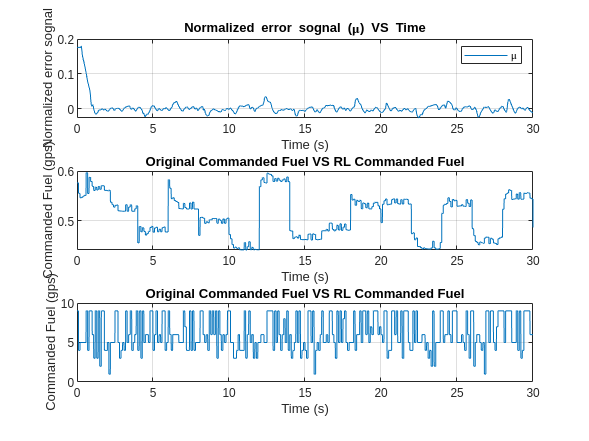


% extract signals from simulation results
time = experiences.SimulationInfo.yout.time;
signals = experiences.SimulationInfo.yout.signals;
labels = {signals.label};

af = signals(contains(labels,'af')).values;
af_ref = signals(contains(labels,'ref')).values;
mu = signals(contains(labels,'mu')).values;
action_Fc = signals(contains(labels,'action_Fc')).values;
selection = signals(contains(labels,'selection')).values;
selection = squeeze(selection(1,1,:));

% plotting
figure(1);
subplot(3,1,1);
plot(time,mu);
title('Normalized error sognal (\mu) VS Time');
legend('\mu');
xlabel('Time (s)') ;
ylabel('Normalized error sognal') ;
grid on;

subplot(3,1,2);
plot(time, action_Fc);
title('Original Commanded Fuel VS RL Commanded Fuel');
xlabel('Time (s)') ;
ylabel('Commanded Fuel (gps)') ;
grid on;

subplot(3,1,3);
plot(time, selection);
title('Original Commanded Fuel VS RL Commanded Fuel');
xlabel('Time (s)') ;
ylabel('Commanded Fuel (gps)') ;
grid on;

## Training progress info

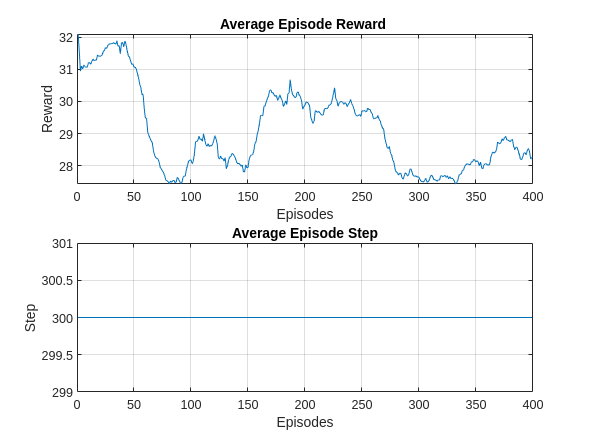

episodes = trainingStats.EpisodeIndex;
episode_reward = trainingStats.EpisodeReward;
episode_step = trainingStats.EpisodeSteps;
episode_avg_reward = trainingStats.AverageReward;
episode_avg_step = trainingStats.AverageSteps;

figure(2);
subplot(2,1,1)
plot(episodes,episode_avg_reward)
title('Average Episode Reward ')
xlabel('Episodes') 
ylabel('Reward') 
grid on

subplot(2,1,2)
plot(episodes,episode_avg_step)
title('Average Episode Step')
xlabel('Episodes') 
ylabel('Step') 
grid on